# PMSM Thermal Test Bench for Battery Electric Vehicle (BEV)

## **Introduction**

The electric motor in a battery electric vehicle (BEV) generates torque for vehicle propulsion. You want to deliver the desired torque at various speed ranges. You also want the motor to have high power efficiency, and for motor control to run the motor in the most efficient region of operation. The motor controller achieves a balance between performance and efficiency. Based upon the operating efficiency of the traction motor, a portion of power supplied to the motor dissipates. This produces heat which raises the temperature of the motor winding and magnet. The motor control maintains the temperature of the motor windings and rotor magnets below a certain value to ensure motor durability and performance. In this example, you learn how to setup a virtual testbench for a permanent magnet synchronous motor (PMSM) to detect thermal failure of the motor during real-world driving scenarios.

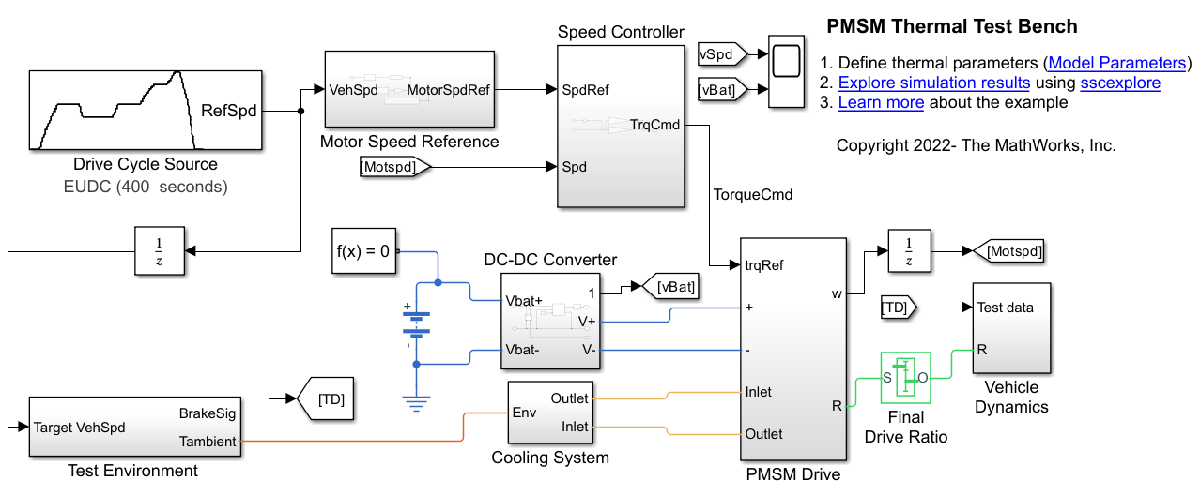

## **Motor Test Bench**

In this example, you develop a test bench at two different fidelity levels:

- Simple motor thermal test

- Detailed motor test 

The simple motor thermal test bench relies upon an available motor efficiency loss map `PMSMmotorLossMap`. The motor loss map at a given fixed base temperature is scaled to the real time winding temperature using Joule heating. The test bench uses a Motor & Drive (System Level`)` block from the Simscape Electrical™ library. This block has a built-in fault node which you can use to set fault criteria. You define the fault scenario as the state when the temperature of the magent `Tmagent` or the temperature of the windings `Twinding` crosses its threshold value. When a fault happens, the current flow through the motor stops. The test ends at this point indicating a thermal failure of the motor. Check out `PMSMThermalTestbenchFst, `use example code below to open the model (It will take some time to load).

If you wish to generate a loss map for the test bench using a Simscape Electrical™ FEM-Parameterized PMSM block, see " Appendix: Generate Motor Loss Map". If you want to run the test for coupled electrothermal simulations, which are integrated with the field oriented controls (FOC), then you can use detailed motor test bench. The simulation time is longer than the simple motor thermal test. The detailed test bench is a high fidelity model, you can add additional motor failure modes into it (i.e., motor electrical performance, over current scenario and FOC performance). For sake of simplicity these other failure modes are not included in this example.

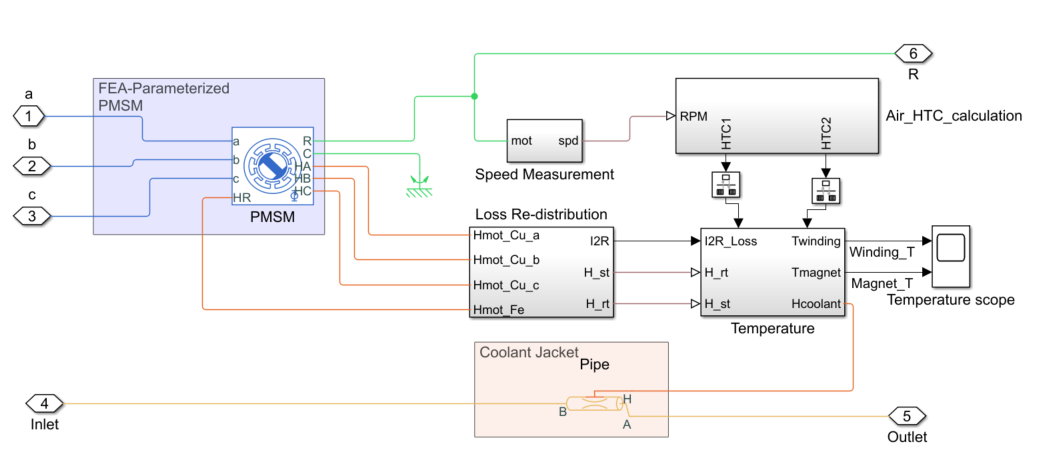

Check out the file `PMSMdetaillTestbench`, and use the example code below to open the detailed test bench model.

## **Temperature Calculation**

The temperature calculation blocks are common to both the models. The block named as Loss Redistribution takes instantaneous motor loss as input. The function of this block is to split the motor power loss into iron and copper loss. The Iron loss is further divided between the stator and the rotor of the motor. The outputs of the block are the three separate loss values.

 The block named Temperature calculates the winding and magnet temperatures. It takes the distributed loss and heat transfer coefficients as input. A Controlled Heat Flow Rate Source block of the Simscape Foundation Library™ applies the three separated losses to their corresponding Thermal Mass blocks. The highest magnet temperature is assumed to be equal to the rotor bridge temperature. Rotor bridge temperature is calculated at Magnet_Temperature node of the Rotor Thermal Block. The Stator_winding node inside the Stator Thermal Block represents the winding temperature. To define the motor thermal parameters, use the `PMSMthermalParams `script`.`

## **Results and Conclusion**

The example script below runs the simple motor thermal test bench to cover a design of experiments (DoE). The script automatically runs the DoE matrix, which is formed by the combination of `gearRatio` and `testCycle` arrays. The test duration is set by `runTime` array, note that the standard test duration differs for vehicle test cycles. The full DoE matrix run takes some time to complete, based on the input arrays. If you want to run a different DoE, update the input arrays in the example code below and run it.

gearRatio = [4.4 4.6 4.8 5.2];% Gear Ratios 
testCycle = ["EUDC","US06"];% Name of the standard test cycle 
runTime = [400 600];% desired time in sec for which test must run.( If runTime > standard test time, then test ie repetated by additinal duration)
summaryTable = PMSMtestBenchRun(gearRatio,testCycle,runTime)

summaryTable = 4×2 table
                       EUDC      US06 
                      ______    ______

    Gear Ratio 4.4    "Pass"    "Fail"
    Gear Ratio 4.6    "Pass"    "Pass"
    Gear Ratio 4.8    "Pass"    "Pass"
    Gear Ratio 5.2    "Pass"    "Pass"


The DoE run summary is captured in `summaryTable`, for inputs. The gear ratio 4.4 fails US06 test cycle. Details are stored in `PMSMbatchRunTemp. A` pre-calculated `PMSMbatchRunTemp` is available for demonstration purposes. To plot the time series of winding and magnet temperatures for entire DoE matrix: load `PMSMbatchRunTemp, `and at MATLAB Command Window enter:

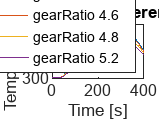

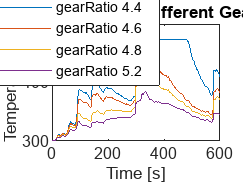

load('PMSMbatchRunTemp.mat');
compT=["W-EUDC","W-US06","M-EUDC","M-US06"];
cycleT=["EUDC" "US06"];
for test = 1:2
   figure("Name",compT(test));
   
    for grr= 1:4
        plot(PMSMallTempBatch{grr,test,1},PMSMallTempBatch{grr,test,2});
        hold on
    end
    hold off;
    xlabel('Time [s]')
    ylabel('Temperature [K]')
    legend("Position", [0.15223,0.7056,0.24606,0.16142])
    legend('gearRatio 4.4','gearRatio 4.6','gearRatio 4.8','gearRatio 5.2')
    title('Winding Temperatures(K) for Different Gear Ratios, '+cycleT(test))
end

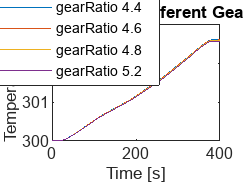

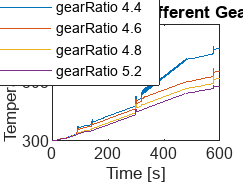

for test = 1:2
    figure("Name",compT(test+2));
    
    for grr= 1:4
        plot(PMSMallTempBatch{grr,test,1},PMSMallTempBatch{grr,test,3});
        hold on
    end
    hold off;
    xlabel('Time [s]')
    ylabel('Temperature [K]')
    legend("Position", [0.15223,0.7056,0.24606,0.16142])
    legend('gearRatio 4.4','gearRatio 4.6','gearRatio 4.8','gearRatio 5.2')
    title('Magnet Temperatures(K) for Different Gear Ratios, '+cycleT(test))
end

At around 350 s, the winding temperature exceeds the threshold value of 473.15K in the US06 run for a gear ratio of 4.4.

## **Appendix: Generate Motor Loss Map**

To model a PMSM at a system level, with fast running thermal calculations, you can generate a motor loss map and integrate it into the system level thermal blocks.

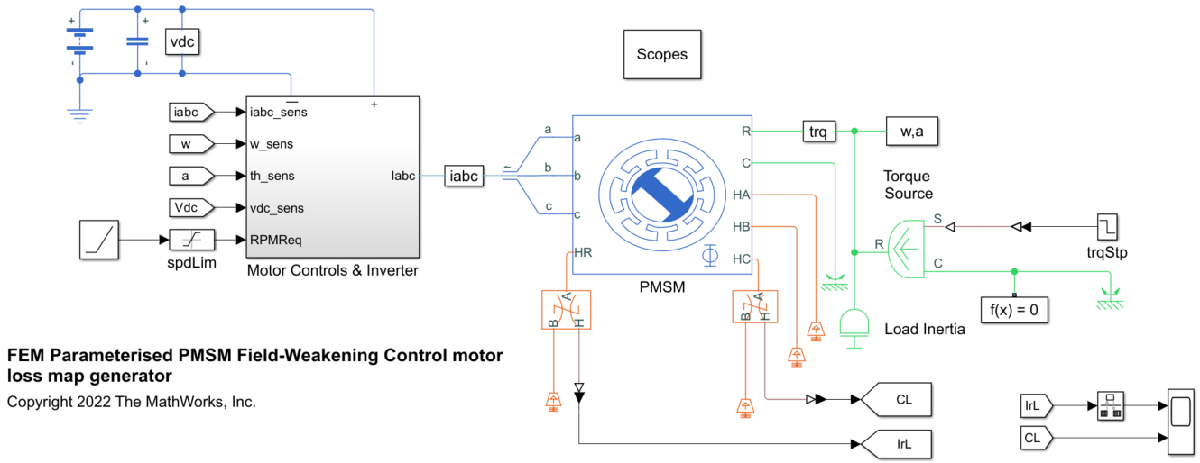

Define the torque and speed vectors for the loss map.

tqMat = [10 20 40 60 80 100 120 150 180 200];% Deesired torque Points N-m 
spMat= [500 1000 2000 3000 4000 5000 6000 7000 8000 10000];% Desired speed pionts RPM
maxMotorPower=60000.00;% Watts Maximum allowed Motor Power. (Operating points with Torque*Angular velocity above maxMotorPower will not run)

To generate the loss map, run the `PMSMgetLoss() `function. This function runs the `PMSMfocControlLossMapGen `model for all values of `tqMat` and `spMat`. Once you generate the motor loss map, save it in a MAT file. In this example, the `PMSMmotorLossMap `stores a precomputed loss map. To change the parameters of the FEM-Parameterized PMSM use `PMSMSystemParamsPopl`. Example code to regenerate the loss map with different torque & speed settings: